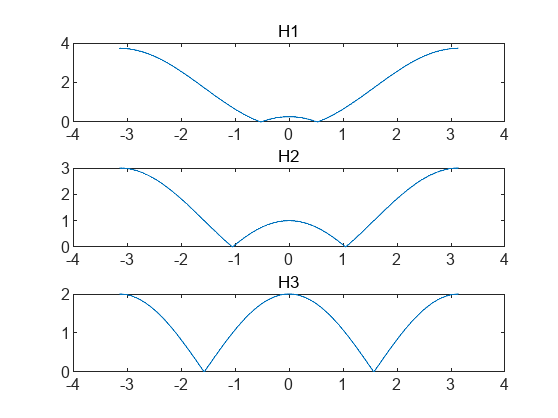

% 7.3
theta = [pi/6 pi/3 pi/2];
w = -pi:0.001:pi;
z = exp(1i*w);
H1 = 1-2*cos(theta(1)).*z.^(-1)+z.^(-2);
H2 = 1-2*cos(theta(2)).*z.^(-1)+z.^(-2);
H3 = 1-2*cos(theta(3)).*z.^(-1)+z.^(-2);
figure
subplot(311)
plot(w, abs(H1));
title('H1');
subplot(312)
plot(w, abs(H2));
title('H2')
subplot(313)
plot(w, abs(H3));
title('H3')

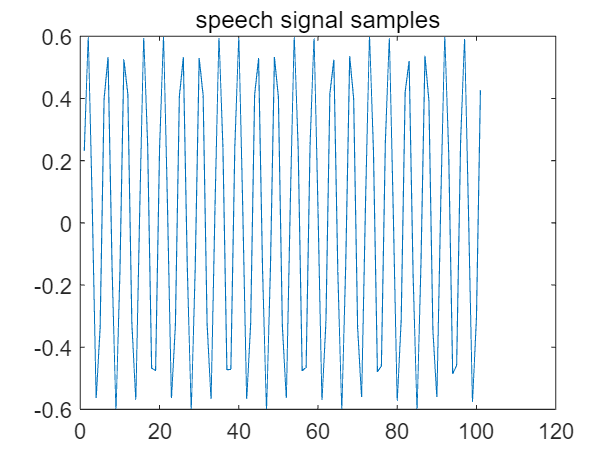

load nspeech1.mat
sound(nspeech1);
figure
plot(nspeech1(100:200));
title('speech signal samples');

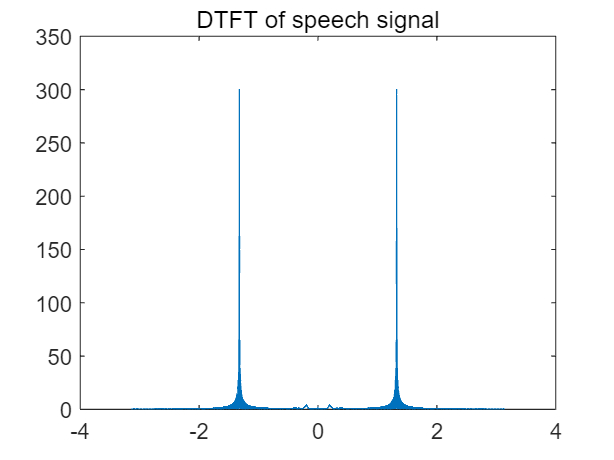

[X ,w]=DTFT(nspeech1(100:1100) ,2^15);
figure
plot(w,abs(X));
title('DTFT of speech signal')

[Xmax,Imax]=max(abs(X));
theta = -w(Imax)

theta = 1.3234

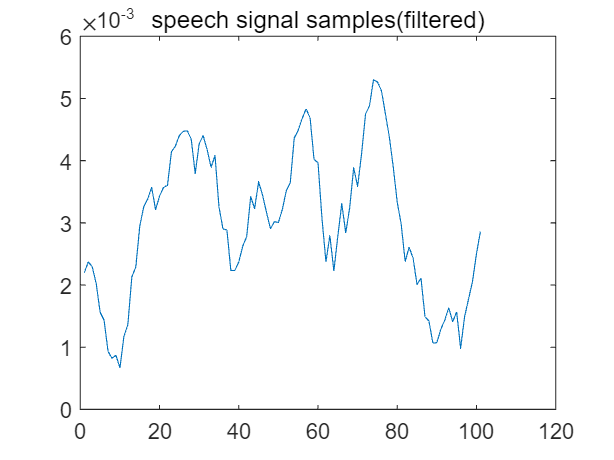


filter_speech = FIRfilter(nspeech1,theta);
sound(filter_speech);
figure
plot(filter_speech(100:200));
title('speech signal samples(filtered)');

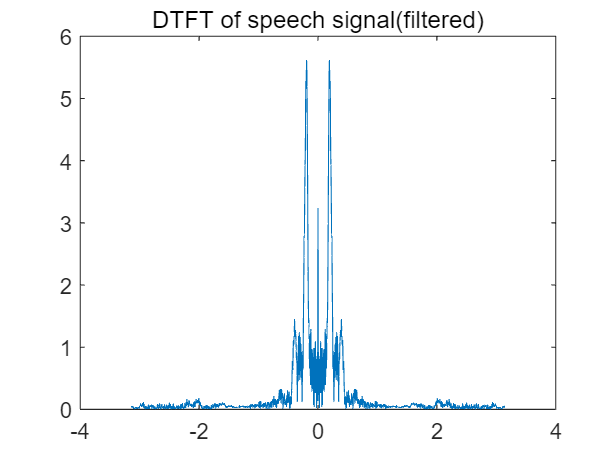

[X_filter ,w]=DTFT(filter_speech(100:1100) ,2^15);
figure
plot(w,abs(X_filter));
title('DTFT of speech signal(filtered)')

%FIR去除特定频率信号

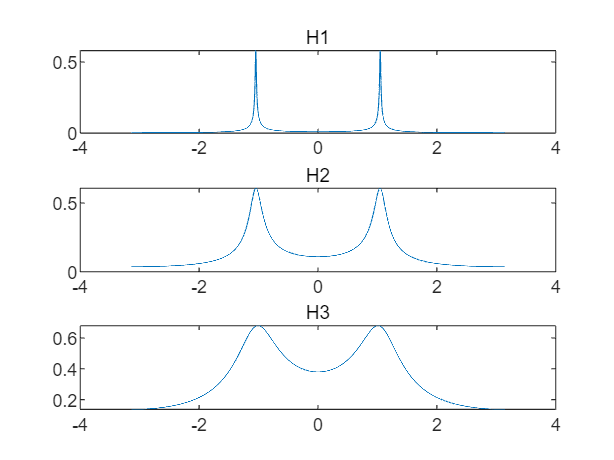

% 7.4
w = -pi:0.001:pi;
z = exp(1i*w);
H1 = (1-0.99)./(1-2*0.99*cos(pi/3).*z.^(-1)+0.99^2.*z.^(-2));
H2 = (1-0.9)./(1-2*0.9*cos(pi/3).*z.^(-1)+0.9^2.*z.^(-2));
H3 = (1-0.7)./(1-2*0.7*cos(pi/3).*z.^(-1)+0.7^2.*z.^(-2));
figure
subplot(311)
plot(w, abs(H1));
title('H1');
subplot(312)
plot(w, abs(H2));
title('H2')
subplot(313)
plot(w, abs(H3));
title('H3')

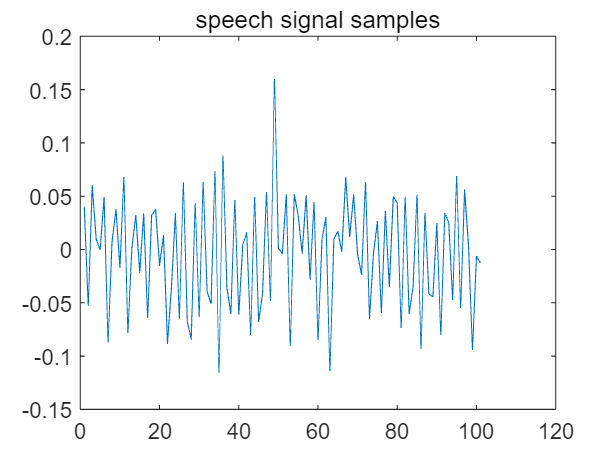

load pcm.mat
sound(pcm);
figure
plot(pcm(100:200));
title('speech signal samples');

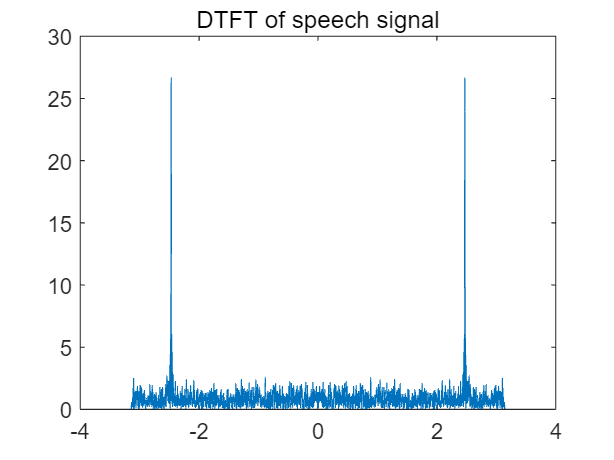

[X ,w]=DTFT(pcm(100:1100) ,2^15);
figure
plot(w,abs(X));
title('DTFT of speech signal')

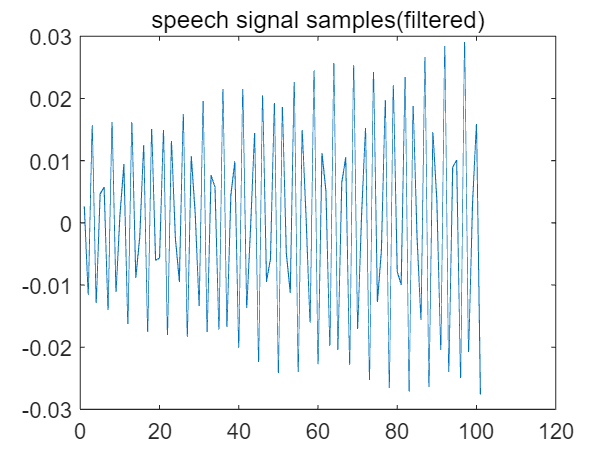


theta = 3146*2*pi/8000;
filter_y =IIRfilter(pcm,0.995);
sound(filter_y);
figure
plot(filter_y(100:200));
title('speech signal samples(filtered)');

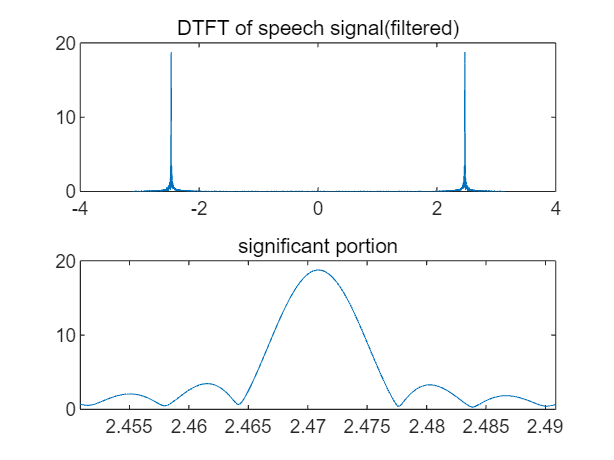

[X_filter ,w]=DTFT(filter_y(100:1100) ,2^15);
figure
subplot(211)
plot(w,abs(X_filter));
title('DTFT of speech signal(filtered)')
subplot(212)
plot(w,abs(X_filter));
title('significant portion')
xlim([theta-0.02,theta+0.02]);

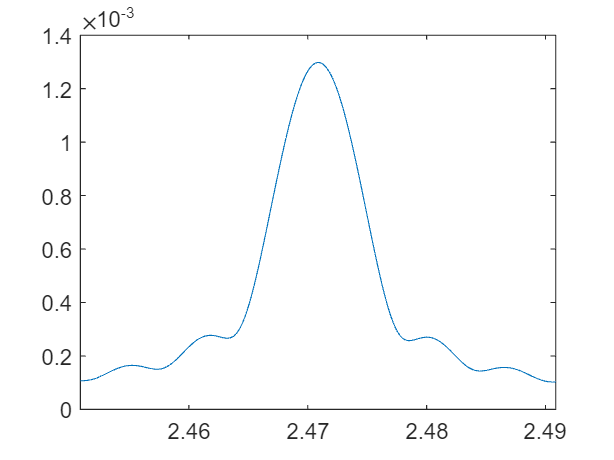


filter_y2 =IIRfilter(pcm,0.9999999);
[Y,w]=DTFT(filter_y2(100:1100) ,2^15);
figure
plot(w,abs(Y));
xlim([theta-0.02,theta+0.02]);

%带宽过窄，导致信号能量极低
%IIR保留特定频率信号

% 7.5
load nspeech2.mat
sound(nspeech2)

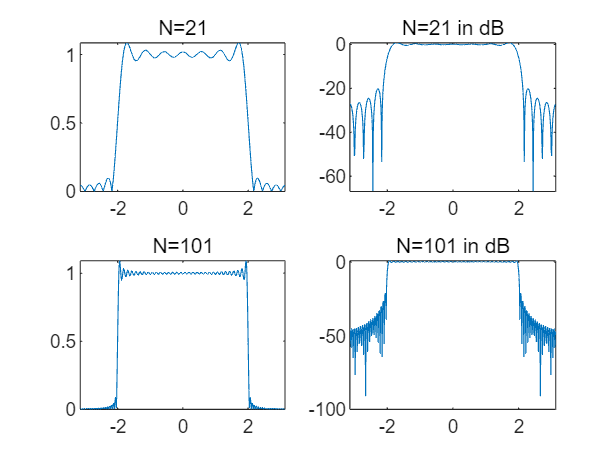

%7.6
h1 =LPFtrunc(21);
[H1,w1]=DTFT(h1,512);
h2 =LPFtrunc(101);
[H2,w2]=DTFT(h2,512);
figure
subplot(221)
plot(w1,(abs(H1)))
title('N=21')
subplot(222)
plot(w1,20*log10(abs(H1)))
title('N=21 in dB' )
subplot(223)
plot(w2,(abs(H2)))
title('N=101')
subplot(224)
plot(w2,20*log10(abs(H2)))
title('N=101 in dB')


filter1=conv(nspeech2,h1);
filter2=conv(nspeech2,h2);
sound(3*filter1)
sound(3*filter2)
%后者噪声更小，但都有噪声

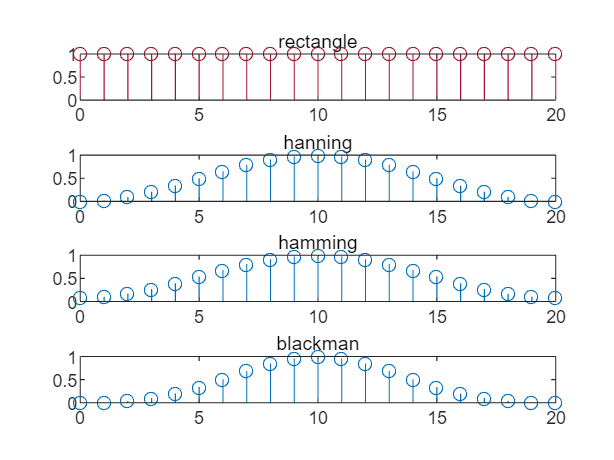

% 7.7
n=0:20;
w1=ones(21);
w2=hann(21);
w3=0.54-0.46*cos(2*pi*n/20);
w4=blackman(21);
figure
subplot(411)
stem(n,w1)
title('rectangle')
subplot(412)
stem(n,w2)
title('hanning')
subplot(413)
stem(n,w3)
title('hamming')
subplot(414)
stem(n,w4)
title('blackman')

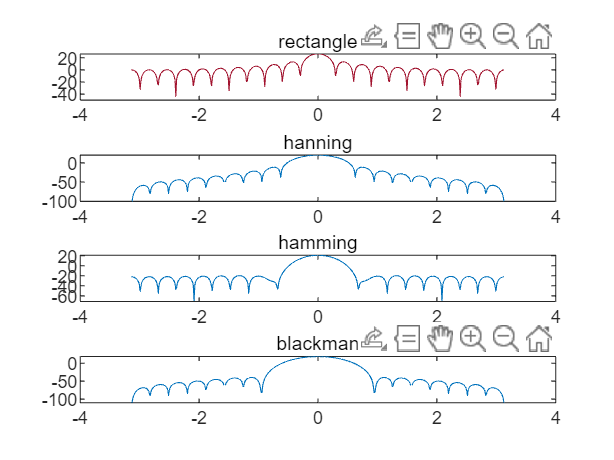


[W1,w]=DTFT(w1,512);
[W2,w]=DTFT(w2,512);
[W3,w]=DTFT(w3,512);
[W4,w]=DTFT(w4,512);
figure
subplot(411)
plot(w,20*log10(abs(W1)))
title('rectangle')
subplot(412)
plot(w,20*log10(abs(W2)))
title('hanning')
subplot(413)
plot(w,20*log10(abs(W3)))
title('hamming')
subplot(414)
plot(w,20*log10(abs(W4)))
title('blackman')


mainlobe_width1 = 0.3*2

mainlobe_width1 = 0.6000

peak_to_sidelobe_amplitude1 = -(26.44-13.25)

peak_to_sidelobe_amplitude1 = -13.1900

%为什么是负数？
mainlobe_width2 = 0.54*2

mainlobe_width2 = 1.0800

peak_to_sidelobe_amplitude2 = -(20-(-11.5))

peak_to_sidelobe_amplitude2 = -31.5000


mainlobe_width3 = 0.56*2

mainlobe_width3 = 1.1200

peak_to_sidelobe_amplitude3 = -(20.7-(-20.7))

peak_to_sidelobe_amplitude3 = -41.4000


mainlobe_width4 = 0.6*2

mainlobe_width4 = 1.2000

peak_to_sidelobe_amplitude4 = -(18.48-(-39.83))

peak_to_sidelobe_amplitude4 = -58.3100

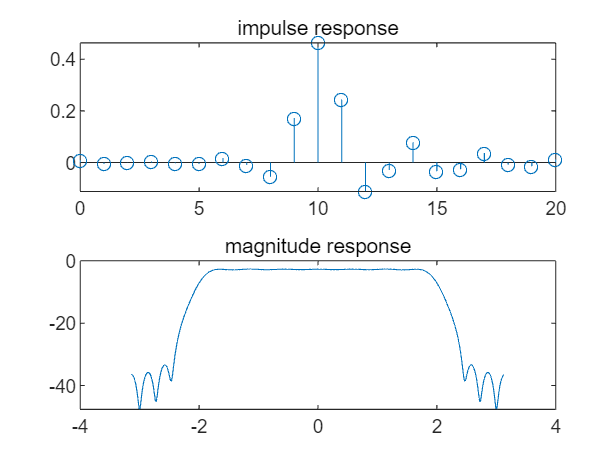


h = w3.*LPFtrunc(21);
[H,w] =DTFT(h,512);
figure
subplot(211)
stem(n,h);
title('impulse response')
subplot(212)
plot(w,20*log10(abs(H)))
title('magnitude response')

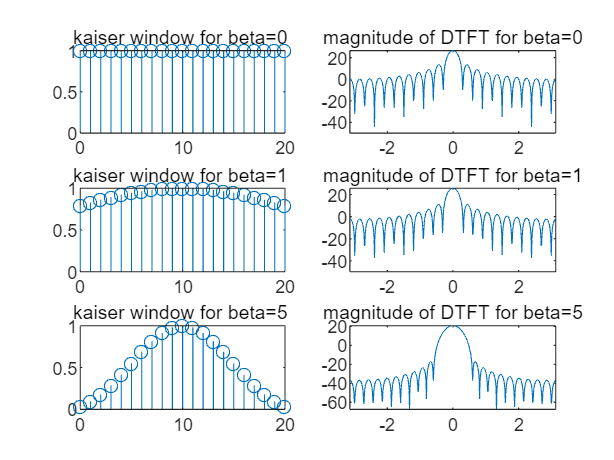

% 7.8
n=0:20;
y1 = kaiser(21,0);
y2 = kaiser(21,1);
y3 = kaiser(21,5);
[Y1,w1]=DTFT(y1,512);
[Y2,w2]=DTFT(y2,512);
[Y3,w3]=DTFT(y3,512);
figure
 subplot(3,2,1) ;
 stem(n,y1) ;
 title('kaiser window for beta=0 ') ;
 subplot(3,2,2) ;
 plot(w1,20*log10(abs(Y1))) ;
 title('magnitude of DTFT for beta=0') ;
 subplot(3,2,3) ;
 stem(n,y2) ;
 title('kaiser window for beta=1 ') ;
 subplot(3,2,4) ;
 plot(w2,20*log10(abs(Y2))) ;
 title('magnitude of DTFT for beta=1') ;
 subplot(3,2,5) ;
 stem(n,y3) ;
 title('kaiser window for beta=5 ') ;
 subplot(3,2,6) ;
 plot(w3,20*log10(abs(Y3))) ;
 title('magnitude of DTFT for beta=5') ;


wp =1.8; wc = 2.0; ws= 2.2; sigma_p = 0.05; sigma_s = 0.005;
sigma =min(sigma_s,sigma_p);
A=-20*log10(sigma)

A = 46.0206

belta =0.5842*(A-21)^0.4+0.07886*(A-21)

belta = 4.0909

N=ceil(1+(A-8)/(2.285*(ws-wp)))

N = 43

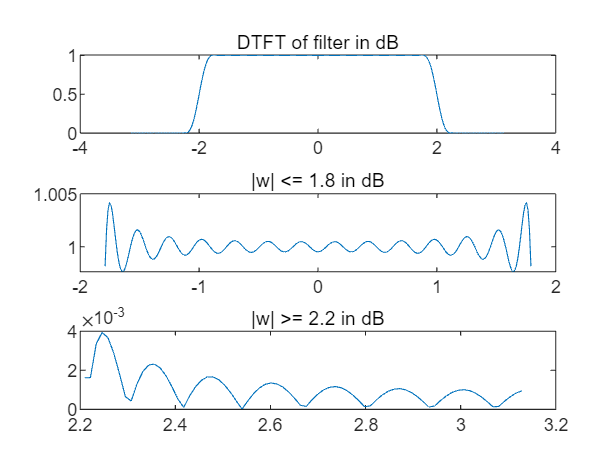

h=(kaiser(N,belta).').*LPFtrunc(N);
[H,w]=DTFT(h,512);
figure
 subplot(3,1,1) ;
 plot(w,abs(H)); 
 title('DTFT of filter in dB') ;
 subplot(3,1,2) ;
 plot(w(abs(w)<=1.8) ,abs(H(abs(w)<=1.8))) ; 
 title('|w| <= 1.8 in dB') ;
 subplot(3,1,3) ;
 plot(w(w>=2.2) ,abs(H(w>=2.2))) ;
 title('|w| >= 2.2 in dB') ;

 passband_ripple = max(abs(H(abs(w)<=1.8)))-min(abs(H(abs(w)<=1.8)))

passband_ripple = 0.0065

 stopband_ripple = max(abs(H(abs(w)>=2.2)))-min(abs(H(abs(w)>=2.2)))

stopband_ripple = 0.0039

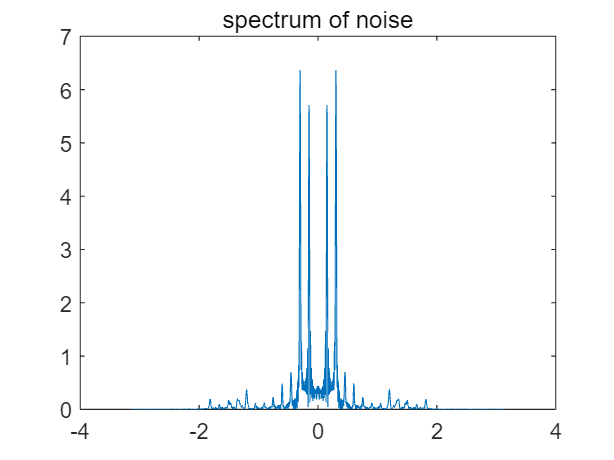

filter_speech2 = conv(h,nspeech2);
[SPEECH,w]=DTFT(filter_speech2(20001:20400),2^15);
figure
plot(w,abs(SPEECH));
title('spectrum of noise')

sound(filter_speech2)
%噪声完全去除


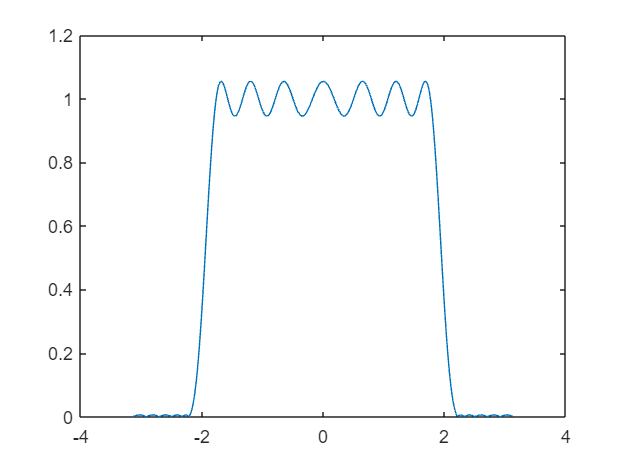

% 8.4
[n,fo,mo,w]=firpmord([wp,ws],[1,0],[sigma_p,sigma_s],2*pi);
b=firpm(n,fo,mo,w);
[FIR,w]=DTFT(b,512);
figure
plot(w,abs(FIR));

passband_ripple = max(abs(FIR(abs(w)<=1.8)))-min(abs(FIR(abs(w)<=1.8)));
stopband_ripple = max(abs(FIR(abs(w)>=2.2)))-min(abs(FIR(abs(w)>=2.2)));
% [n,fo,mo,w]=firpmord(2*pi*fo(2:3)-pi,mo(2:3),[passband_ripple,stopband_ripple],2*pi);
% b=firpm(n,fo,mo,w);
% [FIR,w]=DTFT(b,512);
% figure
% plot(w,abs(FIR));
% passband_ripple = max(abs(FIR(abs(w)<=1.8)))-min(abs(FIR(abs(w)<=1.8)));
% stopband_ripple = max(abs(FIR(abs(w)>=2.2)))-min(abs(FIR(abs(w)>=2.2)));
figure
plot(w,20*log10(abs(FIR)));

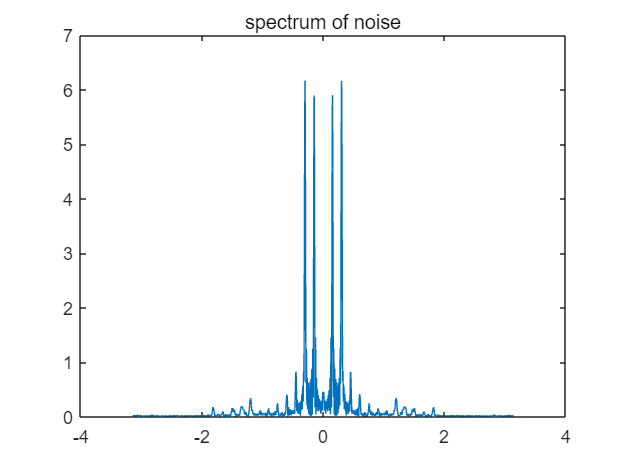

filter_speech2 = conv(b,nspeech2);
[SPEECH,w]=DTFT(filter_speech2(20001:20400),2^15);
figure
plot(w,abs(SPEECH));
title('spectrum of noise')

sound(filter_speech2)


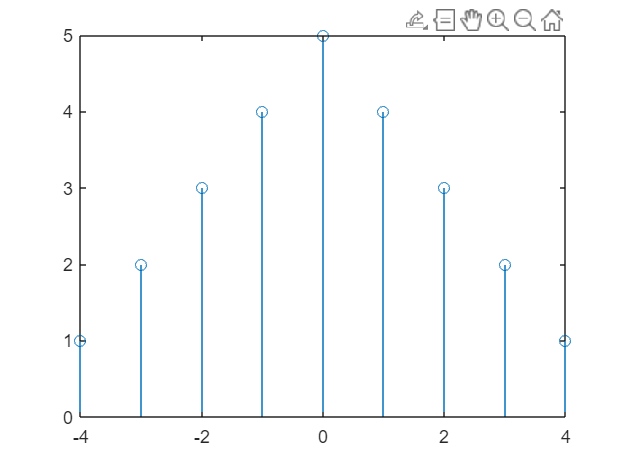

n=-4:4;
y1=[1 1 1 1 1];
y=conv(y1,y1);
stem(n,y)

function y =FIRfilter(x,theta)
n = 0:3;
h = (n==0)-2*cos(theta)*(n==1)+(n==2);
y = conv(x,h);
end

function y = IIRfilter(x,r)
theta = 3146*2*pi/8000;
n=length(x);
y=zeros(1,n);
y(1)=(1-r)*x(1);
y(2)=(1-r)*x(2)+2*r*cos(theta)*y(1);
for k=3:n
    y(k)=(1-r)*x(k)+2*r*cos(theta)*y(k-1)-r^2*y(k-2);
end
end

function h=LPFtrunc(N)
wc=2;
n=0:N-1;
h=wc/pi.*sinc(wc/pi.*(n-(N-1)/2));
end